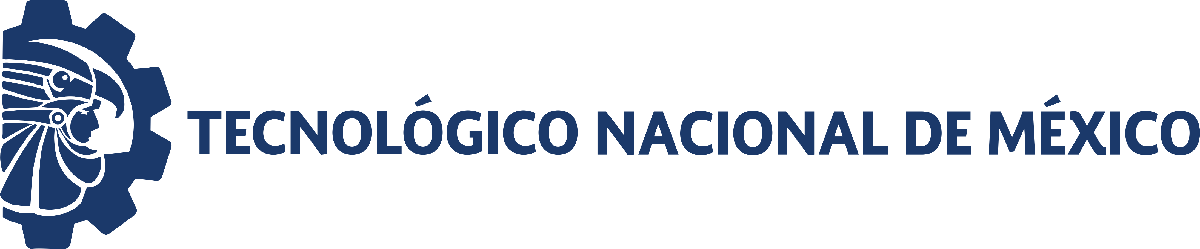                                 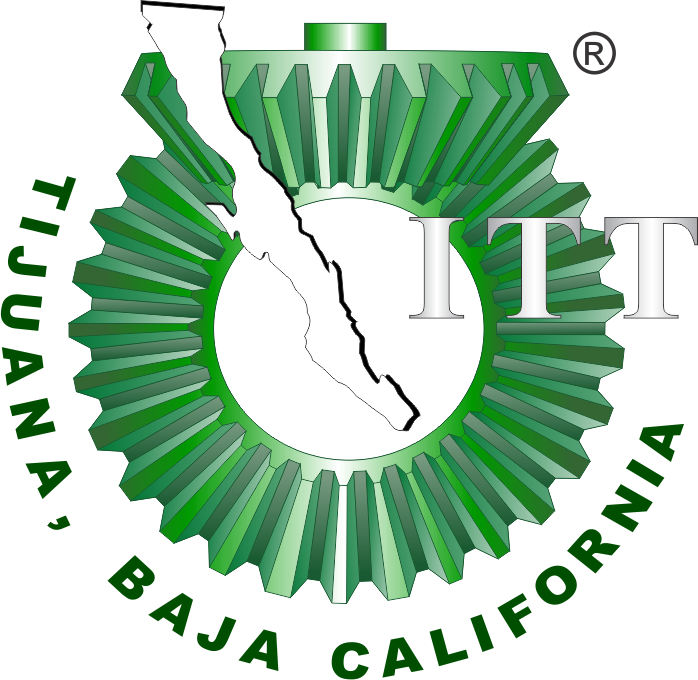

# Práctica 1: Diseño de controladores 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

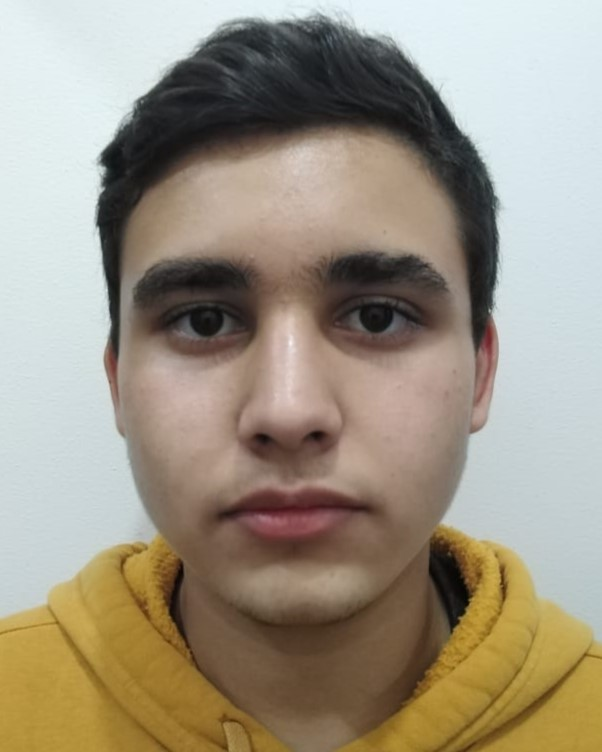

Nombre del alumno: **Rafael Herrera Aguilar**

Número de control: **22212258**

Correo institucional: **l22212258@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Practica_2_MSF';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode45';

## Gráfica Lazo Cerrado

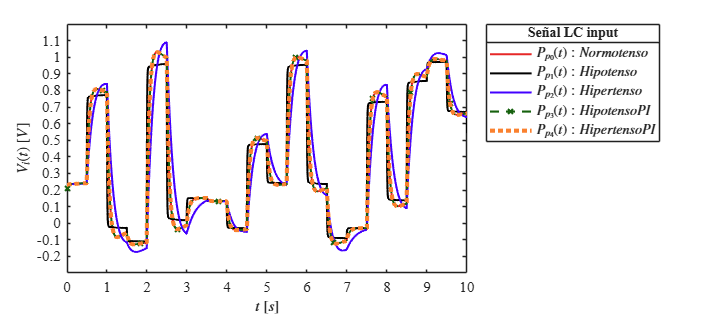

function plotsignals(t,Pp0,Pp1,Pp2,Pp3,Pp4,Signal)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;

    mycolors = [230, 039, 039;
                0, 0, 0;
                067, 0, 255;
                022, 097, 014;
                250, 129, 047;
                145, 018, 188]/255;
    colororder(mycolors)

    p = plot(t,Pp0,'-',t,Pp1,'-',t,Pp2,'-',t,Pp3,'--x',t,Pp4,':',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:100:length(t));
    set(p(5),'LineWidth',3); 
    L = legend('$P_{p_0}(t): Normotenso$','$P_{p_1}(t): Hipotenso$','$P_{p_2}(t): Hipertenso$','$P_{p_3}(t): Hipotenso PI$','$P_{p_4}(t): Hipertenso PI$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,[Signal,' input'],'FontSize',10)

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$V_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    xlim([0,10]); xticks(0:1:10)
    if Signal == "Señal LC"
        ylim([-0.3,1.2]); yticks(-0.2:0.1:1.1)
    end

    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','Vector')
end

Signal = 'Señal LC';
set_param('Practica_2_MSF/Pa','Minimum','-0.2');
set_param('Practica_2_MSF/Pa','Maximum','1');
set_param('Practica_2_MSF/Pa','Seed','106');
set_param('Practica_2_MSF/Pa','Sampletime','0.5');
x1 = sim(file,parameters);
plotsignals(x1.t,x1.Pp0,x1.Pp1,x1.Pp2,x1.Pp3,x1.Pp4,Signal)

## Gráfica Lazo Abierto

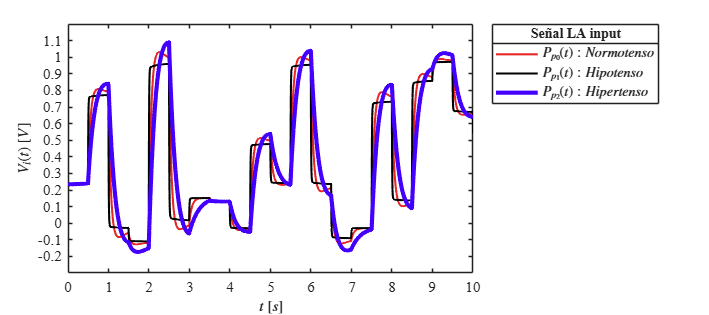

function plotsignals2(t,Pp0,Pp1,Pp2,Signal)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;

    mycolors = [230, 039, 039;
                0, 0, 0;
                067, 0, 255;
                022, 097, 014;
                250, 129, 047;
                145, 018, 188]/255;
    colororder(mycolors)

    p = plot(t,Pp0,'-',t,Pp1,'-',t,Pp2,'-',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(3),'LineWidth',3); 
    L = legend('$P_{p_0}(t): Normotenso$','$P_{p_1}(t): Hipotenso$','$P_{p_2}(t): Hipertenso$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,[Signal,' input'],'FontSize',10)

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$V_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    xlim([0,10]); xticks(0:1:10)
    if Signal == "Señal LA"
        ylim([-0.3,1.2]); yticks(-0.2:0.1:1.1)
    end

    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','Vector')
end

Signal = 'Señal LA';
set_param('Practica_2_MSF/Pa','Minimum','-0.2');
set_param('Practica_2_MSF/Pa','Maximum','1');
set_param('Practica_2_MSF/Pa','Seed','106');
set_param('Practica_2_MSF/Pa','Sampletime','0.5');
x2 = sim(file,parameters);
writematrix(x2.Ppa,'signal.xlsx')
plotsignals2(x2.t,x2.Pp0,x2.Pp1,x2.Pp2,Signal)